Once the Imported LabView data (.lvm) is in the Matlab workspace we can select the Phase A current and time data to create a plot.'The Fourier transform of the signal identifies its frequency components. In MATLAB®, the [fft](docid:matlab_ref.f83-998360) function computes the Fourier transform using a fast Fourier transform algorithm. Use `fft` to compute the discrete Fourier transform of the signal. Plot the power spectrum as a function of frequency. While noise disguises a signal's frequency components in time-based space, the Fourier transform reveals them as spikes in power. In many applications, it is more convenient to view the power spectrum centered at 0 frequency because it better represents the signal's periodicity. Use the [fftshift](docid:matlab_ref.bviss0f-1) function to perform a circular shift on `y`, and plot the 0-centered power. Direct conversion from magnitude to dB is done by 20log10(|x|)

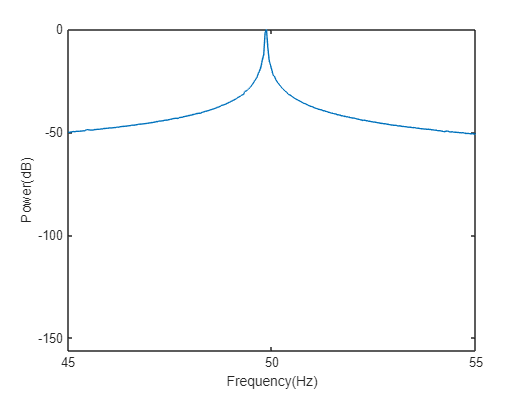

fs = 25600;                 %sampling frequency of Labview
%No Load Healthy Grid Supply
I_a=NoLoadGridHealthy(:,5); %Phase A current data samples
t=NoLoadGridHealthy(:,1);   %Time data samples

y = fft(I_a);               %Fast Fourier Transform
n = length(I_a);            % number of samples
y0 = fftshift(y);           % shift y values
f0 = (-n/2:n/2-1)*(fs/n);   % 0-centered frequency range
powerDb = mag2db(abs(y0./max(y0))); %Matlab built in Decibel Converter 
plot(f0,powerDb)
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([45 55 -inf inf])

The same process is now foloowed for all fault and loading conditions

%No Load 2-turn Stator Fault Grid Supply
I_a1=NoLoadGrid2Turn2(:,5);
t1=NoLoadGrid2Turn2(:,1);
k_int=[1,3,5];
p=1;
n_s=120*50/2;
speed=mean(NoLoadGrid2Turn2(:,9));
s=(n_s-speed)/n_s;

for n_int=1:1:3
F_sth=((n_int/p)*(1-s)+k_int)*50
F_stl=((n_int/p)*(1-s)-k_int)*50
end

F_sth =    99.8102  199.8102  299.8102


F_stl =    -0.1898 -100.1898 -200.1898


F_sth =   149.6203  249.6203  349.6203


F_stl =    49.6203  -50.3797 -150.3797


F_sth =   199.4305  299.4305  399.4305


F_stl =    99.4305   -0.5695 -100.5695


y1 = fft(I_a1);
n1 = length(I_a1);          % number of samples
y01 = fftshift(y1);         % shift y values
f01 = (-n1/2:n1/2-1)*(fs/n1); % 0-centered frequency range
powerDb1 = mag2db(abs(y01)./max(y01));
plot(f01,powerDb1)

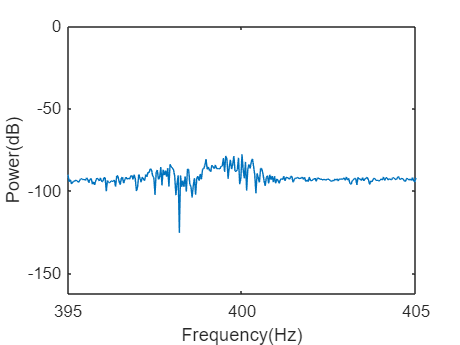

xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([395 405 -inf inf])

%No Load 4-turn Stator Fault Grid Supply
I_a2=NoLoadGrid4Turn(:,5);
t2=NoLoadGrid4Turn(:,1);
k_int=[1,3,5];
p=1;
n_s=120*50/2;
speed=mean(NoLoadGrid4Turn(:,9));
s=(n_s-speed)/n_s;

for n_int=1:1:3
F_sth=((n_int/p)*(1-s)+k_int)*50
F_stl=((n_int/p)*(1-s)-k_int)*50
end

F_sth =    99.7534  199.7534  299.7534


F_stl =    -0.2466 -100.2466 -200.2466


F_sth =   149.5069  249.5069  349.5069


F_stl =    49.5069  -50.4931 -150.4931


F_sth =   199.2603  299.2603  399.2603


F_stl =    99.2603   -0.7397 -100.7397


y2 = fft(I_a2);

n2 = length(I_a2);          % number of samples
f2 = (0:n2-1)*(fs/n2);     % frequency range
y02 = fftshift(y2);         % shift y values
f02 = (-n2/2:n2/2-1)*(fs/n2); % 0-centered frequency range
powerDb2 = mag2db(abs(y02)./max(y02));
plot(f02,powerDb2)

xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([295 305 -inf inf])

%No Load Broken Rotor Bar Fault Grid Supply
I_a3=NoLoadBRBGrid(:,5);

Unrecognized function or variable 'NoLoadBRBGrid'.

t3=NoLoadBRBGrid(:,1);
k_int=[1,2,3,4,5];
p=1;
n_s=120*50/2;
speed=mean(NoLoadBRBGrid(:,9));
s=(n_s-speed)/n_s;

F_bbl=(1-2*k_int*s)*50
F_bbh=(1+2*k_int*s)*50

y3 = fft(I_a3);

n3 = length(I_a3);          % number of samples
f3 = (0:n3-1)*(fs/n3);     % frequency range
y03 = fftshift(y3);         % shift y values
f03 = (-n3/2:n3/2-1)*(fs/n3); % 0-centered frequency range
powerDb3 = mag2db(abs(y03)./max(y03));
plot(f03,powerDb3)
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([45 55 -60 inf])

%Full Load Healthy Grid Supply
I_a=FullLoadGridHealthy(:,5);
t=FullLoadGridHealthy(:,1);

y = fft(I_a);
n = length(I_a);          % number of samples
y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
powerDb = mag2db(abs(y0./max(y0)));
plot(f0,powerDb)
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([45 55 -100 inf])

%Full Load BRB Fault Grid Supply
I_a3=FullLoadBRBGrid(:,5);
t3=FullLoadBRBGrid(:,1);
k_int=[1,2,3,4,5];
p=1;
n_s=120*50/2;
speed=mean(FullLoadBRBGrid(:,9));
s=(n_s-speed)/n_s;

F_bbl=(1-2*k_int*s)*50
F_bbh=(1+2*k_int*s)*50

y3 = fft(I_a3);

n3 = length(I_a3);          % number of samples
f3 = (0:n3-1)*(fs/n3);     % frequency range
y03 = fftshift(y3);         % shift y values
f03 = (-n3/2:n3/2-1)*(fs/n3); % 0-centered frequency range
powerDb3 = mag2db(abs(y03)./max(y03));
plot(f03,powerDb3)
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([45 55 -100 inf])

%No Load Healthy Inverter Supply
I_a=NoLoadInvHealthy(:,5); %Phase A current data samples
t=NoLoadInvHealthy(:,1);   %Time data samples

y = fft(I_a);               %Fast Fourier Transform
n = length(I_a);            % number of samples
y0 = fftshift(y);           % shift y values
f0 = (-n/2:n/2-1)*(fs/n);   % 0-centered frequency range
powerDb = mag2db(abs(y0./max(y0))); %Matlab built in Decibel Converter 
plot(f0,powerDb)
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([40 60 -inf inf])

%No Load 2-turn Stator Fault Inverter Supply
I_a1=NoLoadinv2Turn(:,5);
t1=NoLoadinv2Turn(:,1);

y1 = fft(I_a1);
n1 = length(I_a1);          % number of samples
y01 = fftshift(y1);         % shift y values
f01 = (-n1/2:n1/2-1)*(fs/n1); % 0-centered frequency range
powerDb1 = mag2db(abs(y01));
plot(f01,powerDb1)
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([40 60 -inf inf])

%No Load 4-turn Stator Fault Inverter Supply
I_a2=NoLoadinv4Turn(:,5);
t2=NoLoadinv4Turn(:,1);

y2 = fft(I_a2);

n2 = length(I_a2);          % number of samples
f2 = (0:n2-1)*(fs/n2);     % frequency range
y02 = fftshift(y2);         % shift y values
f02 = (-n2/2:n2/2-1)*(fs/n2); % 0-centered frequency range
powerDb2 = mag2db(abs(y02));
plot(f02,powerDb2)
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
axis([40 60 -inf inf])

%No Load Broken Rotor Bar Fault Grid Supply
I_a3=NoLoadInv(:,5);
t3=NoLoadInv(:,1);

y3 = fft(I_a3);

n3 = length(I_a3);          % number of samples
f3 = (0:n3-1)*(fs/n3);     % frequency range
y03 = fftshift(y3);         % shift y values
f03 = (-n3/2:n3/2-1)*(fs/n3); % 0-centered frequency range
powerDb3 = mag2db(abs(y03));
plot(f03,powerDb3)
xlabel('Frequency')
ylabel('Power(dB)')
axis([40 60 -inf inf])

%Full Load Healthy Inverter Supply
I_a=FullLoadInvHealthy(:,5);
t=FullLoadInvHealthy(:,1);

y = fft(I_a);
n = length(I_a);          % number of samples
y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
powerDb = mag2db(abs(y0./max(y0)));
plot(f0,powerDb)
xlabel('Frequency')
ylabel('Power(dB)')
axis([40 60 -inf inf])

%Full Load BRB Fault Inverter Supply
I_a3=FullLoadInv(:,5);
t3=FullLoadInv(:,1);

y3 = fft(I_a3);

n3 = length(I_a3);          % number of samples
f3 = (0:n3-1)*(fs/n3);     % frequency range
y03 = fftshift(y3);         % shift y values
f03 = (-n3/2:n3/2-1)*(fs/n3); % 0-centered frequency range
powerDb3 = mag2db(abs(y03));
plot(f03,powerDb3)
xlabel('Frequency')
ylabel('Power(dB)')
axis([40 60 -inf inf])